# 3.4. Электрический и магнитный диполи

#### Электрический дипольный момент зарядов +Q и -Q на расстоянии d друг от друга

clear
syms rot(x) grad(x) div(x) sprod(x,y) vprod(x,y)
syms p Q d
p==Q*d

$$ans = p=Q\,d$$

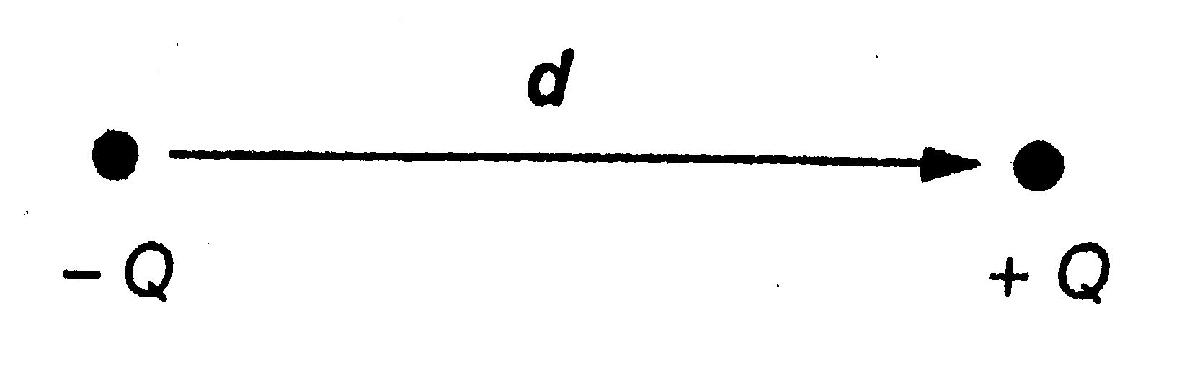

#### Магнитный дипольный момент элементарного тока


$$\mathit{\mathbf{m}}=I\;A\;{\mathit{\mathbf{u}}}_N$$


syms m I A u_N
m==I*A*u_N

$$ans = m=A\,\text{I}\,u_{N}$$

% u_N = единичный вектор

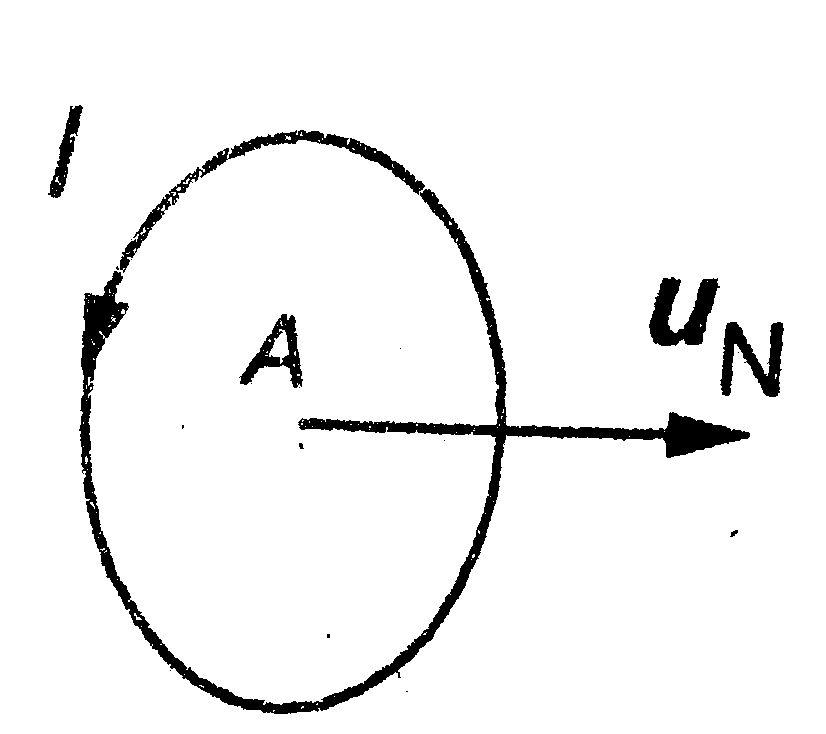

#### Потенциал вдали от электрического диполя


$$V=\frac{1}{4\pi \;\varepsilon_0 }\frac{p\;\mathrm{cos}\left(\theta \right)}{r^2 }$$


syms V epsilon0 p theta r
V==1/(4*pi*epsilon0)*p*cos(theta)/r^2

$$ans = V=\frac{p\,\cos\left(\theta \right)}{4\,\epsilon_{0}\,r^{2}\,\pi }$$

syms p r
V==1/(4*pi*epsilon0)*sprod(p,r)/r^3

$$ans = V=\frac{\mathrm{sprod}\left(p,r\right)}{4\,\epsilon_{0}\,r^{3}\,\pi }$$

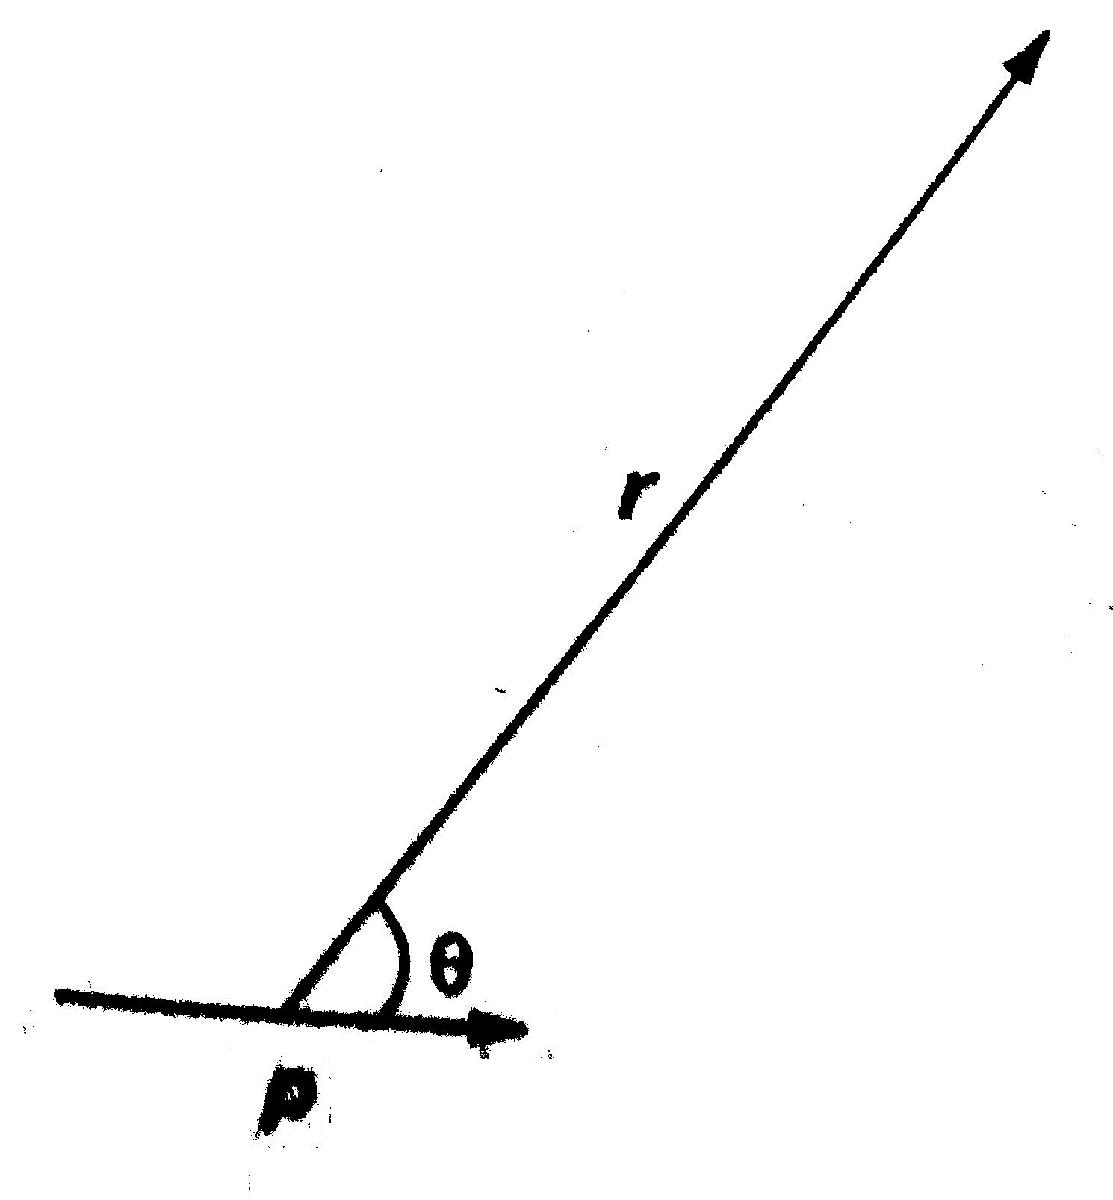

#### Электрическое поле 


$$\mathit{\mathbf{E}}=-\mathrm{grad}\;V$$


syms E V
E==-grad(V)

$$ans = \text{E}=-\mathrm{grad}\left(V\right)$$

В частности, в сферических полярных координатах

syms E_r V E_theta d(f,x,n)
E_r==-d(V,r,1)

$$ans = E_{r}=-d\left(V,r,1\right)$$

syms V theta
E_theta=-1/r*d(V,theta,1)

$$E\_theta = -\frac{d\left(V,\theta ,1\right)}{r}$$

#### Поле вдали от магнитного диполя

syms B_r B_theta mu0 m theta r
B_r==mu0/(4*pi)*2*m*cos(theta)/r^3

$$ans = B_{r}=\frac{m\,\mu_{0}\,\cos\left(\theta \right)}{2\,r^{3}\,\pi }$$

B_theta==(mu0/(4*pi))*m*sin(theta)/r^3

$$ans = B_{\theta }=\frac{m\,\mu_{0}\,\sin\left(\theta \right)}{4\,r^{3}\,\pi }$$

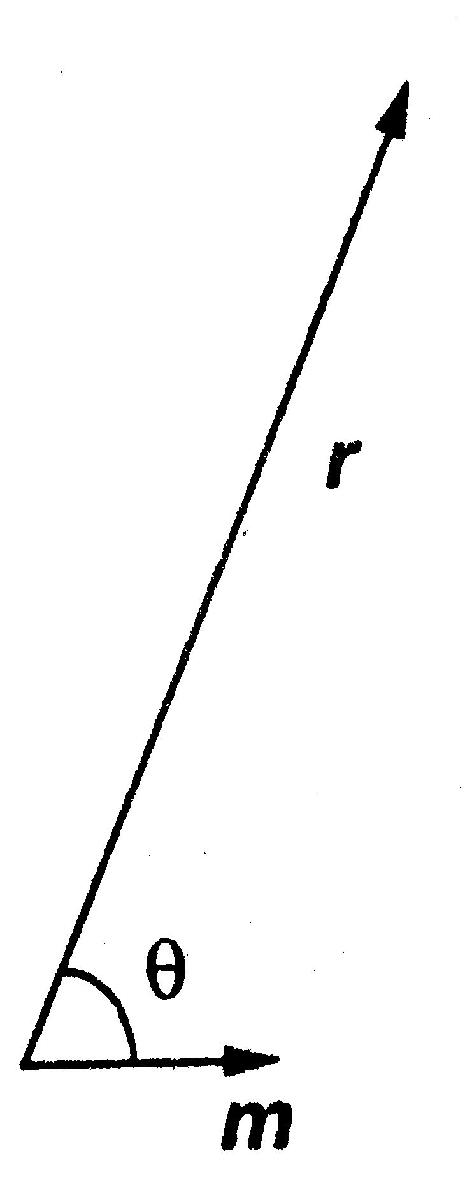

#### Векторный потенциал магнитного диполя


$$A=\frac{\mu_0 }{4\;\pi }\frac{\mathit{\mathbf{m}}\times \mathit{\mathbf{r}}}{r^3 }$$


syms A m r
A==mu0/(4*pi)*vprod(m,r)/r^3

$$ans = A=\frac{\mu_{0}\,\mathrm{vprod}\left(m,r\right)}{4\,r^{3}\,\pi }$$

#### Вращающий момент диполя во внешнем поле

syms tau_e tau_m alpha B p E m B
tau_e==p*E*sin(alpha), tau_m==m*B*sin(alpha)

$$ans = \tau_{e}=\text{E}\,p\,\sin\left(\alpha \right)$$

$$ans = \tau_{m}=B\,m\,\sin\left(\alpha \right)$$


$$\tau_e =\mathit{\mathbf{p}}\times \mathit{\mathbf{E}}$$



$$t_m =\mathit{\mathbf{m}}\times \mathit{\mathbf{B}}$$


tau_e==vprod(p,E), tau_m==vprod(m,B)

$$ans = \tau_{e}=\mathrm{vprod}\left(p,\text{E}\right)$$

$$ans = \tau_{m}=\mathrm{vprod}\left(m,B\right)$$

#### Потенциальная энергия диполя во внешнем поле


$$W_e =-\mathit{\mathbf{p}}\cdot \mathit{\mathbf{E}}=-p\;E\;\mathrm{cos}\;\alpha$$


syms W_e p E alpha W_m m B
W_e==-sprod(p,E)==-p*E*cos(alpha)

$$ans = \left(W_{e}=-\mathrm{sprod}\left(p,\text{E}\right)\right)=-\text{E}\,p\,\cos\left(\alpha \right)$$


$$W_m =-\mathit{\mathbf{m}}\cdot \mathit{\mathbf{B}}=-m\;B\;\mathrm{cos}\;\alpha$$


W_m==-sprod(m,B)==-m*B*cos(alpha)

$$ans = \left(W_{m}=-\mathrm{sprod}\left(m,B\right)\right)=-B\,m\,\cos\left(\alpha \right)$$

#### Сила, действующая на диполь во внешнем поле


$$\mathit{\mathbf{F}}=\left(\mathit{\mathbf{p}}\cdot \nabla \right)\mathit{\mathbf{E}}$$


syms p nabla F E
F==(sprod(p,nabla))*E

$$ans = F=\text{E}\,\mathrm{sprod}\left(p,\mathrm{nabla}\right)$$


$$\mathit{\mathbf{F}}=\left(\mathit{\mathbf{m}}\cdot \nabla \right)\mathit{\mathbf{B}}+\mathit{\mathbf{m}}\left(\nabla \times \mathit{\mathbf{B}}\right)$$


F==sprod(m,nabla)*B+m*vprod(nabla,B)

$$ans = F=B\,\mathrm{sprod}\left(m,\mathrm{nabla}\right)+m\,\mathrm{vprod}\left(\mathrm{nabla},B\right)$$

В частности, если диполь направлен вдоль x-оси и если rot(B)=0.

(Сила направлена в сторону увеличения поля)


$$\mathit{\mathbf{F}}=p_x \frac{\partial }{\partial x}\mathit{\mathbf{E}}$$



$$\mathit{\mathbf{F}}=m_x \frac{\partial }{\partial x}\mathit{\mathbf{B}}$$


syms p_x E m_x B x d(f,x,n)
F==p_x*d(E,x,1), F==m_x*d(B,x,1)

$$ans = F=p_{x}\,d\left(\text{E},x,1\right)$$

$$ans = F=m_{x}\,d\left(B,x,1\right)$$

#### Электрический дипольный момент незаряженного тела с распределенного заряда 


$$\mathit{\mathbf{p}}=\int \mathit{\mathbf{r}}\;\rho \;\mathrm{dv}$$


syms rho(v) r
p==int(r*rho,v)

$$ans(v) = p=\int r\,\rho \left(v\right)\mathrm{d}v$$

% v = объем тела

#### Общее определение магнитного дипольного момента


$$\mathit{\mathbf{m}}=\frac{1}{2}\int \mathit{\mathbf{r}}\times \mathit{\mathbf{j}}\;\mathrm{dv}$$


syms r j(v)
m==1/2*int(vprod(r,j),v)

$$ans = m=\frac{\int \mathrm{vprod}\left(r,j\left(v\right)\right)\mathrm{d}v}{2}$$